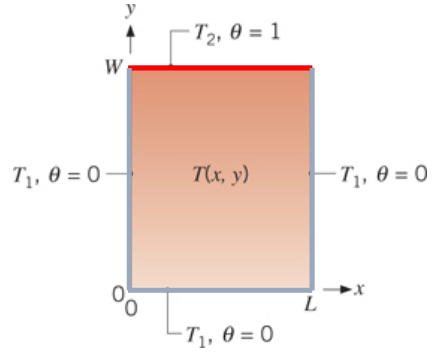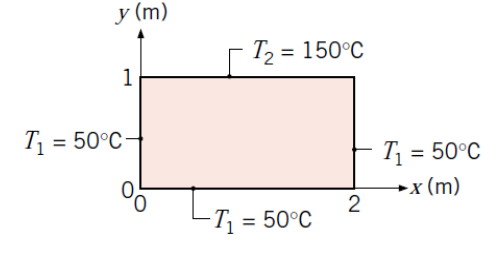

clear all
clf
syms theta(x,y) x y T(x,y) T_diff_x(x,y) T_diff_y(x,y)
T2 = 150 + 273.15;
T1 = 50 + 273.15;
n_end = 20; % antal led på polynomiet
W = 1; %højde
L = 2; %brede
sums = 0;


Equations

for n = 1:n_end
    sum_n = ((-1)^(n+1) + 1) / n * sin(n * pi * x / L) * sinh(n*pi*y/L) / sinh(n*pi*W/L);
    sums = sums + sum_n;
end

theta(x,y) = 2/pi * sums;
T(x,y) = T2 - T1*theta(x,y) + T2*theta(x,y);
% eq = theta1 == (Ttest - T2)/(T2-T1);
% Ttest = solve(eq, Ttest)

T_diff_x(x,y) = diff(T(x,y), x);
T_diff_y(x,y) = diff(T(x,y), y);

Mesh creation

scalar_filed_size = 50;  % change sizes here
x_lin = linspace(0,L,scalar_filed_size);
y_lin = linspace(0,W,scalar_filed_size);

for i = 1:scalar_filed_size
    for j = 1:scalar_filed_size
        scalar_field(i,j) = T(x_lin(i),y_lin(j));
        DX(i,j) = T_diff_x(x_lin(i),y_lin(j));
        DY(i,j) = T_diff_y(x_lin(i),y_lin(j));
    end
end

[X,Y] = meshgrid(x_lin,y_lin);
%rotation of the grid to mach figure
X = X' 

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0.0408    0

Y = Y'

Y =          0    0.0204    0.0408    0.0612    0.0816    0.1020    0.1224    0.1429    0.1633    0.1837    0.2041    0.2245    0.2449    0.2653    0.2857    0.3061    0.3265    0.3469    0.3673    0.3878    0.4082    0.4286    0.4490    0.4694    0.4898    0.5102    0.5306    0.5510    0.5714    0.5918    0.6122    0.6327    0.6531    0.6735    0.6939    0.7143    0.7347    0.7551    0.7755    0.7959    0.8163    0.8367    0.8571    0.8776    0.8980    0.9184    0.9388    0.9592    0.9796    1.0000
         0    0.0204    0.0408    0.0612    0.0816    0.1020    0.1224    0.1429    0.1633    0.1837    0.2041    0.2245    0.2449    0.2653    0.2857    0.3061    0.3265    0.3469    0.3673    0.3878    0.4082    0.4286    0.4490    0.4694    0.4898    0.5102    0.5306    0.5510    0.5714    0.5918    0.6122    0.6327    0.6531    0.6735    0.6939    0.7143    0.7347    0.7551    0.7755    0.7959    0.8163    0.8367    0.8571    0.8776    0.8980    0.9184    0.9388    0.9592    0.9796    1

Plot

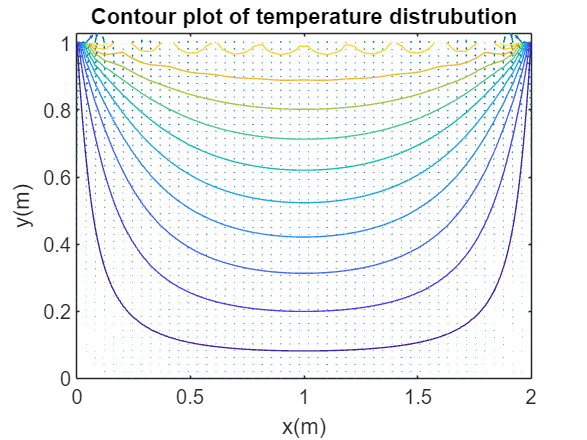

q = quiver(X,Y,DX,DY);
hold on
contour(X,Y,scalar_field)
title('Contour plot of temperature distrubution')
ylabel('y(m)')
xlabel('x(m)')
% q.ShowArrowHead = 'off';
% q.Marker = '.';
% q.AutoScaleFactor(0.5)
hold off